%%A little statistics
%%Part 1
%checking the error function
normcdf(0)

ans = 0.5000

normcdf(0.1)

ans = 0.5398

normcdf(0.24)

ans = 0.5948

%checking the inverse of the error function
norminv(0.5)

ans = 0

norminv(0.5398)

ans = 0.0999

norminv(0.5948)

ans = 0.2399

%values match pretty close to inputs
%check probabilities for sigma = 1,2,5
norminv(0.8413)

ans = 0.9998

norminv(0.9772)

ans = 1.9991

norminv(1)

ans = Inf

%close!
%negative numbers would appear if we try
%probability that is below 0.5
norminv(0.3)

ans = -0.5244

%the integral goes from negative inf to z, and
%probability of 1/2 is at z=0
%the negative makes sense because it assumes that 
%we are looking to the right of the mean centered
%at 0
%hence things on the left would be negative

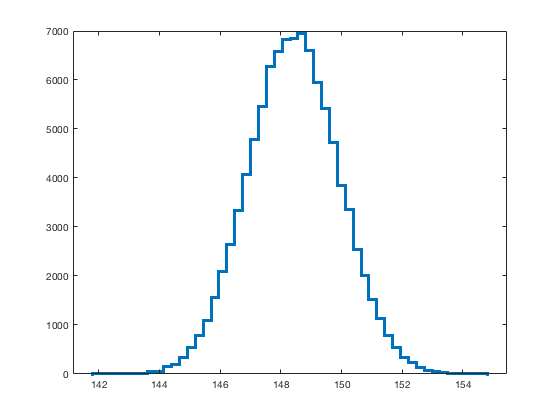

%%Part2
dist = random('Lognormal',5.,0.01,[1,100000]);
histogram(dist,50,'DisplayStyle',"stairs",'LineWidth',3)

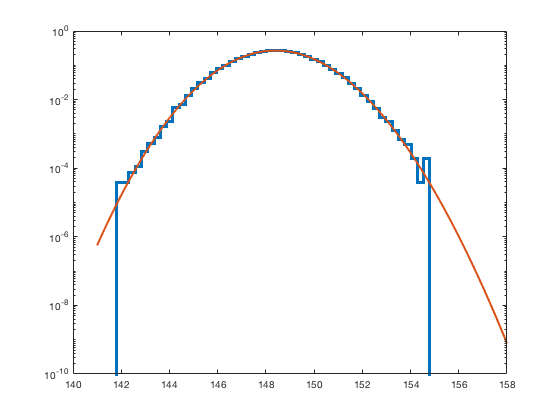

histogram(dist,50,'DisplayStyle',"stairs",'LineWidth',3,"Normalization","pdf")
hold on
x = linspace(141,158,1000);
pd = makedist("Lognormal","mu",5.,"sigma",0.01);
plot(x,pdf(pd,x),"LineWidth",2);
set(gca,'YScale','log')

%%Part 3
%value = 151
%what is the probability that the measurement of
%value 151 isn't noise or is not produced by the
% signal free distribution, instead being
% a physical measurement, if higher is signal-like
%another way to see this is the probability that
%the selected value or anything smaller is given
%by the probability distribution

%integral from -inf to 151 of pd (probability
%distribution)
cdf(pd,151)

ans = 0.9580

%convert this probability into sigma
norminv(0.9580)

ans = 1.7279

%the sigma is 1.7279

%%Part 4
%try values 148,140,200,166,120,150
%see the associated sigmas
cdf(pd,148)

ans = 0.3902

norminv(cdf(pd,148))

ans = -0.2788

cdf(pd,140)

ans = 2.6773e-09

norminv(cdf(pd,140))

ans = -5.8358

cdf(pd,200)

ans = 1

norminv(cdf(pd,200))

ans = Inf

cdf(pd,166)

ans = 1

norminv(cdf(pd,166))

ans = Inf

cdf(pd,120)

ans = 1.6196e-100

norminv(cdf(pd,120))

ans = -21.2508

%as expected, values within the distribution
%yield answers between 0 and 1
%values much higher than the distribution
%yield answers close to 1
%values much lower than the distribution give
%negative probabilities

%%Poison Distribution